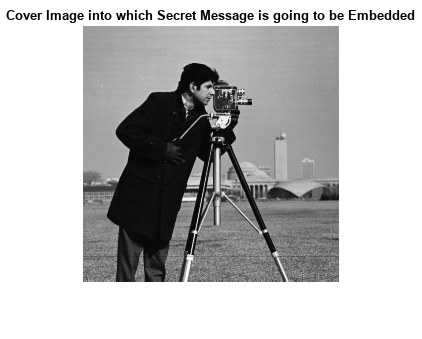

clear all
close all
clc

cover_image = double(imread('cameraman.tif'));
figure, imshow(cover_image / 255);
title("Cover Image into which Secret Message is going to be Embedded")

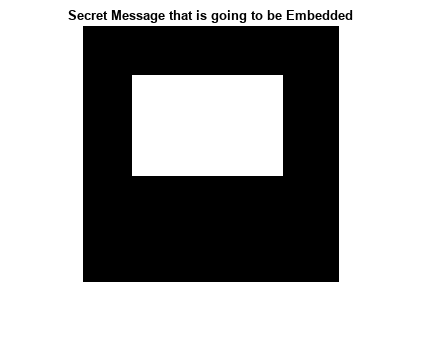


y = cover_image;
secret_image = zeros(256, 256);
secret_image(50:150, 50:200) = 1;
figure, imshow(secret_image)
title("Secret Message that is going to be Embedded")


save m.dat secret_image -ascii

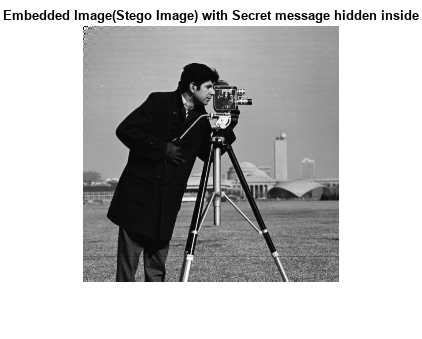


% Watermarking
% DCT of RGB of cover image
ci_r = cover_image(:,:,1);


dx1 = dct2(ci_r);  dx11 = dx1 ;


load m.dat  
% binary_mask_for_watermarking
g = 1; % Coefficient of watermark's strength
[rm, cm] = size(m);

% Adding the secret Image rows and columns into cover Image's All DCT coefficients  
dx(1:rm, 1:cm) = dx1(1:rm, 1:cm) + g * m;


% Inverse DCT for the Embedded Image creation
y1 = idct2(dx);

y(:,:,1) = y1;


figure, imshow(y/255)
title("Embedded Image(Stego Image) with Secret message hidden inside")

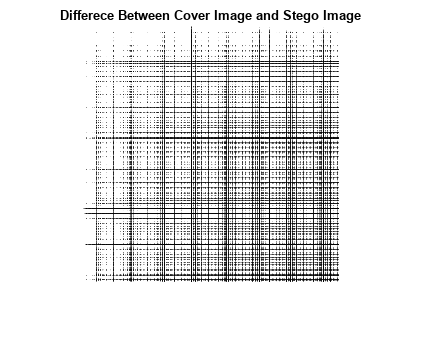

figure, imshow(abs(y-cover_image)*100) 
title("Differece Between Cover Image and Stego Image")

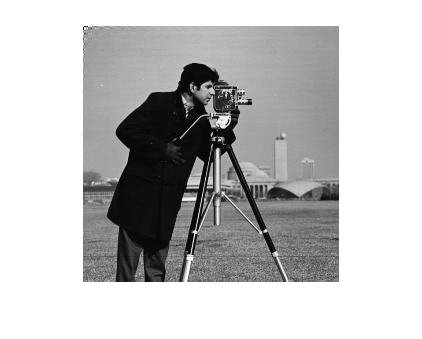

% Convert to uint8
A = uint8(y);
imshow(A)

% Convert Image into Bitsream for Communication
s = size(A);
B = dec2bin(A(:), 8)';
C = B(:)' - '0';

% Apply BPSK modulation, repetition encoding, and hard decision decoding
Eb_Nodb = 10;
Eb_No = 10 .^ (Eb_Nodb/10);
n = 3;
k = 1;
R = k/n;
sigma_coded = sqrt(1/(2*Eb_No));
% Initialize the Transmitter's Output
comm_out = zeros(1, n);

disp(length(C))

      524288



% Transmitter and Receiver
for j = 1:length(C)
    % Take a single value of bitstream
    msg = C(j);
% TRANSMITTER
    % Repetition 3 encoding
    msg_encoded = [msg msg msg];
    % BPSK modulation
    mod_out = -1 + 2 * msg_encoded;
% CHANNEL
    % Add Gussian noise
    channel_out = mod_out + sigma_coded * randn(1, n);
% RECEIVER    
    % demodulating
    demod_out = channel_out > 0;
    % Hard decision decoding and output of end to end communication
    comm_out(j) = sum(demod_out) >= 2;
end

% Convert  Bitsream into Image for Decryption
bitstream = num2str(comm_out); bitstream = bitstream(bitstream ~= ' ');
disp(size(bitstream));

           1      524288



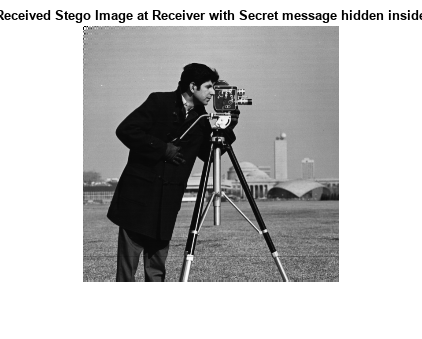

X = uint8(bin2dec(reshape(num2str(bitstream), 8, [])'));
I = reshape(X, s);
imshow(I);
title("Received Stego Image at Receiver with Secret message hidden inside")

% Convert back to the original data type of y
com = cast(I, class(y));

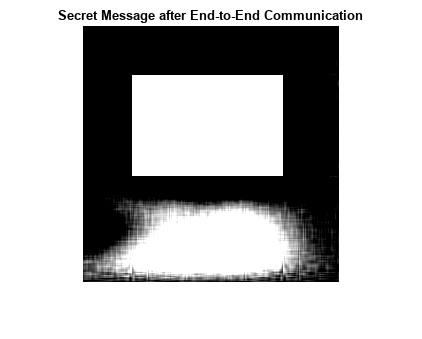

z = com;
[r,c,s] = size(z) ;

% De-watermarking
% Clean image (known mask)
y = z;
dy1 = dct2(y(:,:,1));


dy(1:rm, 1:cm) = dy1(1:rm, 1:cm) - g * m;
comm = (dy1(1:rm, 1:cm) - dx1(1:rm, 1:cm));

com = cast(comm, class(y));
imshow(com)
title('Secret Message after End-to-End Communication')

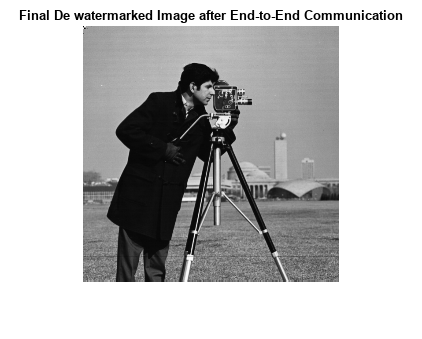



y11 = idct2(dy);

yy(:,:,1) = y11;

figure, imshow(yy/255)
title('Final De watermarked Image after End-to-End Communication')